## Load and reshape the Image

%  Load the image
A = double(imread('im5.jfif'));
A = A / 255; % Normalize the image
img_size = size(A); %store the size of image
X = reshape(A, img_size(1) * img_size(2), 3); %resize into 3 channel RGB


## Initialize the Centroids

K = 2;  %Number of Centroids
max_iters = 10; %Max iterations
initial_centroids = kMeansInitCentroids(X, K); %get initial centroids


## Run K-Means Kernel

% Run K-Means
[centroids, ~] = runkMeans(X, initial_centroids, max_iters);

K-Means iteration 1/10...
K-Means iteration 2/10...
K-Means iteration 3/10...
K-Means iteration 4/10...
K-Means iteration 5/10...
K-Means iteration 6/10...
K-Means iteration 7/10...
K-Means iteration 8/10...
K-Means iteration 9/10...
K-Means iteration 10/10...


## Retrieve the Compressed Image

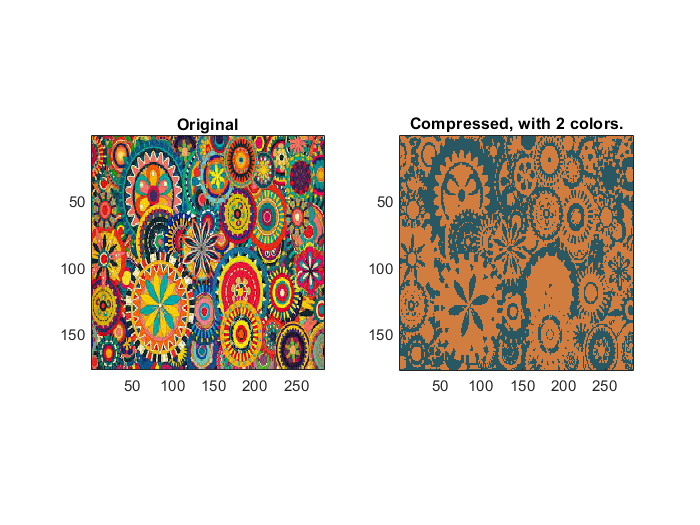

% Find closest cluster members
idx = findClosestCentroids(X, centroids);

X_comp = centroids(idx,:);

%Resize the compressed image
X_comp = reshape(X_comp, img_size(1), img_size(2), 3);

% Display the original image 
figure;
subplot(1, 2, 1);
imagesc(A); 
title('Original');
axis square

%Display Compressed Image
subplot(1, 2, 2);
imagesc(X_comp)
title(sprintf('Compressed, with %d colors.', K));
axis square